Van der Pol 방정식은 다음과 같이 정의됩니다:


$$\ddot{x} - \mu(1 - x^2)\dot{x} + x = 0$$


이를 1차 미분방정식 두 개로 나누어 표현하면:


$$\dot{x_1} = x_2$$



$$\dot{x_2} = \mu(1 - x_1^2)x_2 - x_1$$


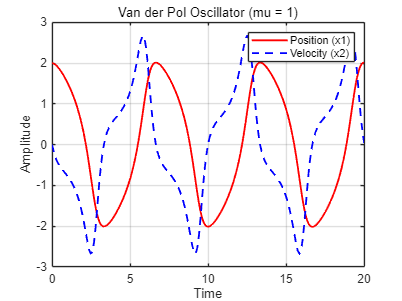

% Van der Pol 방정식

% mu 값 설정 (비선형성 제어)
mu = 1.0;

% Van der Pol 방정식 정의
% 상태 벡터 X = [x1, x2] (x1: 위치, x2: 속도)
vdp = @(t, X) [X(2); mu * (1 - X(1)^2) * X(2) - X(1)];

% 초기 조건 설정
initial_conditions = [2.0; 0.0];  % 초기 위치 x1(0) = 2, 초기 속도 x2(0) = 0

% 시간 범위 설정
tspan = [0 20];  % 0에서 20초까지

% ode45를 이용하여 Van der Pol 방정식 풀이
[t, X] = ode45(vdp, tspan, initial_conditions);

figure;
plot(t, X(:,1), 'r-', 'LineWidth', 1.5);  % 위치 x1 그래프
hold on;
plot(t, X(:,2), 'b--', 'LineWidth', 1.5);  % 속도 x2 그래프
hold off;

title('Van der Pol Oscillator (mu = 1)');
xlabel('Time');
ylabel('Amplitude');
legend('Position (x1)', 'Velocity (x2)');
grid on;